# Laboratory 1: Intro,Stability,LM

Consider a Chua circuit described by the following state equation:

$\dot x =\left[\matrix{\dot x_1 \cr \dot x_2 \cr \dot x_3}\right] = f(x,u)=\left[\matrix{\alpha(x_2 - x_1 - \rho(x_1)) \cr x_1 -x_2 +x_3+u \cr -\beta x_2 - R x_3}\right] $, $\rho(x_1) = \frac{2x_1^3}{7} - \frac{8x_1}{7}$

where $\alpha = 10$, $\beta = \frac{100}{7}$ and $R = 0$.

### Exercise 1

clc
clear
close all

1. Implement the system in Simulink.

open("chua_sim.slx")

2. Perform a simulation of duration $Tfin = 60 s$, with $u(t) = 0$ $\forall t$, and random initial condition $x(0)$ close to the origin. Generate a figure with a 3D Plot of the simulated trajectory. Generate another figure, showing the state signals. Perform another similar simulation, where the initial condition is slightly changed with respect to the previous one. Compare the trajectories and signals resulting from the two simulations.

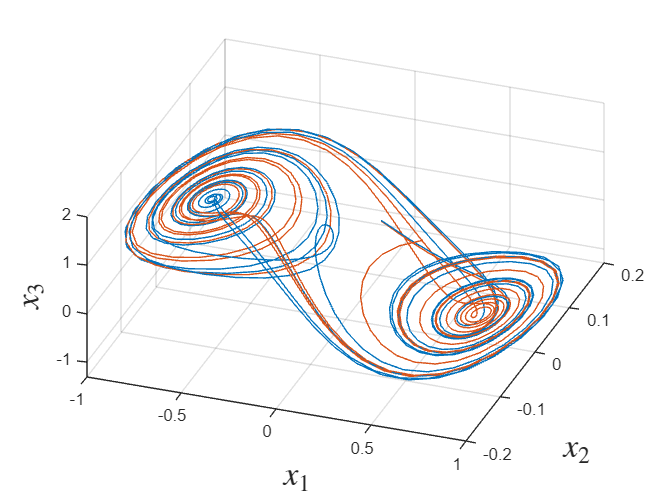

% INITIALIZATION
u_bar = 0;
x0 = rand(3,1)*0.1;
x0_p = x0+[0;0;0.01];
Tfin = 60;

% SIMULATION
sim("chua_sim.slx");

%PLOTTING RESULTS
figure(1)
grid, hold on
plot3(x1(:,1),x2(:,1),x3(:,1))          % nominal trajectory
plot3(x1(:,2),x2(:,2),x3(:,2))          % perturbed trajectory
xlabel('$x_1$','interpreter','latex','fontsize',20)
ylabel('$x_2$','interpreter','latex','fontsize',20)
zlabel('$x_3$','interpreter','latex','fontsize',20)
view(20,50)

Since the system is a chaotic one, in particular it's a **strange attractor**,even if we apply a small difference in the initial condition the perturbed trajectory $x_p$ will be completly differrent from the nominal one $x$ (after some time) as we can see.

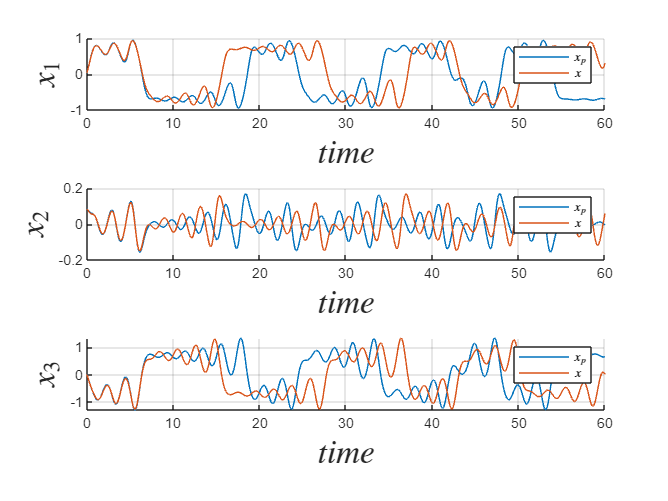

figure(2)
t = linspace(0,Tfin,length(x1(:,1)));
subplot(3,1,1)
hold on; grid on
plot(t,x1(:,1))
plot(t,x1(:,2))
ylabel('$x_1$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off
subplot(3,1,2)
hold on; grid on
plot(t,x2(:,1))
plot(t,x2(:,2))
ylabel('$x_2$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off
subplot(3,1,3)
hold on;grid on
plot(t,x3(:,1))
plot(t,x3(:,2))
ylabel('$x_3$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off

### Exercise 2

clc
clear
close all

1. Find the equilibrium points $\bar x$  of the system, corresponding to the constant input $u(t) = \bar u = 0$, $\forall t$.

x=sym('x',[3 1],'real');
u=sym('u',1,'real');

%SYSTEM
a=10;
b=100/7; 
R=0;

rho=2/7*x(1)^3-8/7*x(1);

f(1,1) = a*(x(2)-x(1)-rho);
f(2,1) = x(1)-x(2)+x(3)+u; 
f(3,1) = -b*x(2)-R*x(3);

%EQULIBRIUM POINTS
u_bar = 0;

f = subs(f,u,u_bar)

$$f = \left(\begin{array}{c} -\frac{20\,{x_{1}}^{3}}{7}+\frac{10\,x_{1}}{7}+10\,x_{2}\\ x_{1}-x_{2}+x_{3}\\ -\frac{100\,x_{2}}{7} \end{array}\right)$$

sol = solve(f,x);

for i=1:length(sol.x1)
    x_bar(:,i) = double([sol.x1(i) sol.x2(i) sol.x3(i)]);
end
x_bar %equilibrium points

x_bar =          0    0.7071   -0.7071
         0         0         0
         0   -0.7071    0.7071


2. For each equilibrium point found in Step 1, linearize the system around this point. Linearization can be performed computing the matrices:


$$A = \left[\matrix{\frac{\partial f}{\partial x}}\right]_{(\bar x, \bar u)} B = \left[\matrix{\frac{\partial f}{\partial u}}\right]_{(\bar x, \bar u)}$$


where $\frac{\partial f}{\partial x}$ and $\frac{\partial f}{\partial u}$ are the Jacobians of $f$ with respect to $x$ and $u$, respectively. $A$ and $B$ are the matrices of the linearized system around the given equilibrium point.

3. Considering the linearized systems of Step 2, study the stability of the equilibrium points found in Step 1.

A_lin = jacobian (f,x)

$$A\_lin = \left(\begin{array}{ccc} \frac{10}{7}-\frac{60\,{x_{1}}^{2}}{7} & 10 & 0\\ 1 & -1 & 1\\ 0 & -\frac{100}{7} & 0 \end{array}\right)$$

for i = 1:size(x_bar,2)
   A = subs(A_lin,x,x_bar(:,i))
   eig(double(A))
end

$$A = \left(\begin{array}{ccc} \frac{10}{7} & 10 & 0\\ 1 & -1 & 1\\ 0 & -\frac{100}{7} & 0 \end{array}\right)$$

ans =    2.5163 + 0.0000i
  -1.0439 + 2.6497i
  -1.0439 - 2.6497i


$$A = \left(\begin{array}{ccc} -\frac{20}{7} & 10 & 0\\ 1 & -1 & 1\\ 0 & -\frac{100}{7} & 0 \end{array}\right)$$

ans =   -4.3637 + 0.0000i
   0.2533 + 3.0478i
   0.2533 - 3.0478i


$$A = \left(\begin{array}{ccc} -\frac{20}{7} & 10 & 0\\ 1 & -1 & 1\\ 0 & -\frac{100}{7} & 0 \end{array}\right)$$

ans =   -4.3637 + 0.0000i
   0.2533 + 3.0478i
   0.2533 - 3.0478i


As we can see for each matrix A associated to an equilibrium point we have at least one eigenvalues with real part greater than 0 so all the equilibrium points are **instable**

### Exercise 3

1. Using the Simulink model, perform a simulation of duration $Tfin = 5 s$, with $u(t) = 0$, $\forall t$, and $x(0) = x_0$, where $x_0$ is close (but not equal) to one of the equilibrium points found at Step 1 of Exercise 2. Generate a figure with a 3D Plot of the simulated trajectory. On the same figure, plot also the equilibrium points. Generate another figure, showing the state signals. Provide an interpretation of the obtained results, considering also the stability analysis carried out in Exercise 2.

2. Repeat Step 1 with a different initial state $x(0) = x_{p0}$, where $x_{p0}$ is close (but not equal) to $x_0$. Add the obtained trajectory plot to the first figure of Step 1. Add the obtained state signals plot to the second figure of Step 1.

3. Repeat Steps 1 and 2 several times, considering larger simulation times $Tfin$. Discuss the possibility of predicting the future behavior of the system state, providing indications on the time horizon over which predictions can be considered reliable (note that this time horizon depends on the initial conditions).

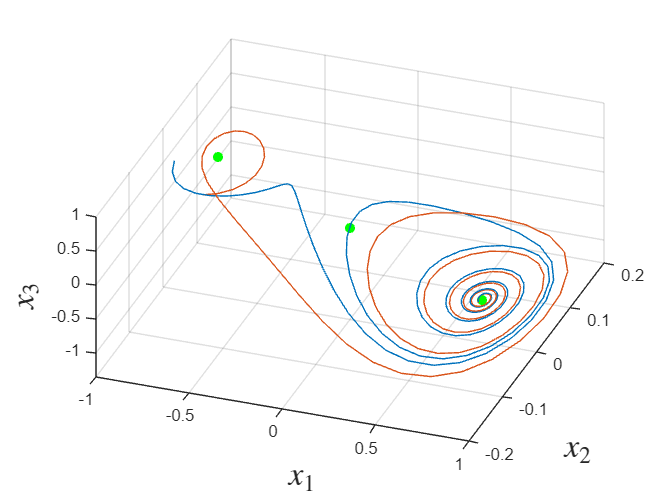

x0 = x_bar(:,2)+randn(3,1)*0.01;
x0_p = x0+[0;0;0.01];
Tfin=15;

sim("chua_sim.slx");

%PLOTTING RESULTS
figure(1)
grid, hold on
plot3(x1(:,1),x2(:,1),x3(:,1))          % nominal trajectory
plot3(x1(:,2),x2(:,2),x3(:,2))          % perturbed trajectory
xlabel('$x_1$','interpreter','latex','fontsize',20)
ylabel('$x_2$','interpreter','latex','fontsize',20)
zlabel('$x_3$','interpreter','latex','fontsize',20)
for i = 1:size(x_bar,2)
    scatter3(x_bar(1,i),x_bar(2,i),x_bar(3,i),'green','filled','o');
end
view(20,50)

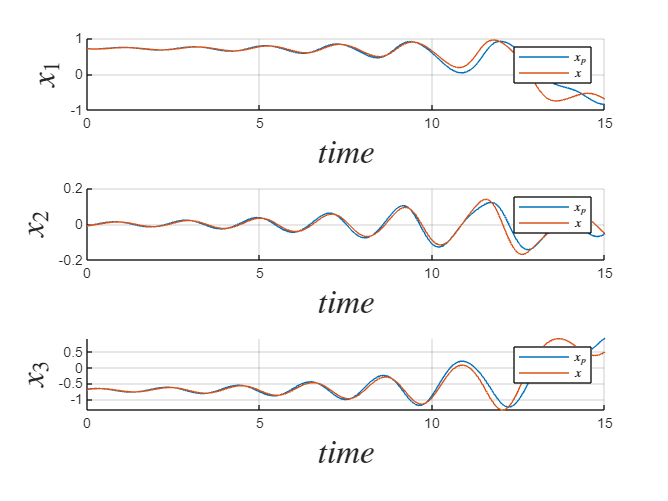

figure(2)
t = linspace(0,Tfin,length(x1(:,1)));
subplot(3,1,1)
hold on; grid on
plot(t,x1(:,1))
plot(t,x1(:,2))
ylabel('$x_1$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off
subplot(3,1,2)
hold on; grid on
plot(t,x2(:,1))
plot(t,x2(:,2))
ylabel('$x_2$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off
subplot(3,1,3)
hold on;grid on
plot(t,x3(:,1))
plot(t,x3(:,2))
ylabel('$x_3$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
legend('$x_p$','$x$','interpreter','latex')
hold off

### Exercise 4

1. Let $A$ and $B$ be the matrices of the system linearized around the equilibrium point $\bar u = 0$, $\bar x = (0, 0, 0)$. On the basis of these matrices, design a linear controller, finalized at stabilizing the same equilibrium point.

A = subs(A_lin,x,x_bar(:,1))

$$A = \left(\begin{array}{ccc} \frac{10}{7} & 10 & 0\\ 1 & -1 & 1\\ 0 & -\frac{100}{7} & 0 \end{array}\right)$$

f(2,1) = f(2,1)+u; %Adding u to the second function
B_lin = jacobian(f,u);
B = subs(B_lin,u,u_bar);
k = place(double(A),double(B),[-1 -2 -3]);

2. Apply the controller to the system implemented in Simulink.

open("chua_controlled_sim.slx");

3. For the controlled system, repeat Step 1 of Exercise 3 several times, considering different initial conditions and a simulation time Tfin ≥ 30 s. Discuss the obtained results.

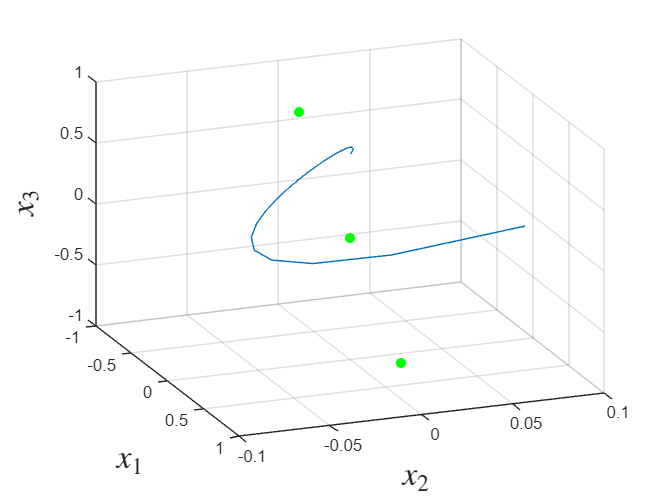

Tfin = 30;
x0 = rand(3,1)*0.2;
sim("chua_controlled_sim.slx");

figure
grid, hold on
plot3(x(:,1),x(:,2),x(:,3))          % nominal trajectory
xlabel('$x_1$','interpreter','latex','fontsize',20)
ylabel('$x_2$','interpreter','latex','fontsize',20)
zlabel('$x_3$','interpreter','latex','fontsize',20)
for i = 1:size(x_bar,2)
    scatter3(x_bar(1,i),x_bar(2,i),x_bar(3,i),'green','filled','o');
end
view(20,50)

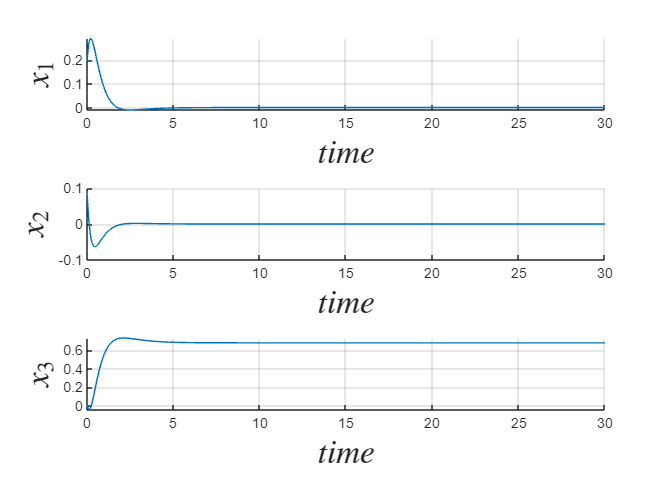

figure
t = linspace(0,Tfin,length(x(:,1)));
subplot(3,1,1)
hold on; grid on
plot(t,x(:,1))
ylabel('$x_1$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
hold off
subplot(3,1,2)
hold on; grid on
plot(t,x(:,2))
ylabel('$x_2$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
hold off
subplot(3,1,3)
hold on;grid on
plot(t,x(:,3))
ylabel('$x_3$','interpreter','latex','fontsize',20)
xlabel('$time$','interpreter','latex','fontsize',20)
hold off